# **Telco Customer Churn Prediction**

## **A Comparative Study of Logistic Regression and Random Forest**  

**Elnara Mammadova - 210026788**

close all
clear all
clc

Load the mat file

load finalModels.mat

# A. Test the Logistic Regression Model

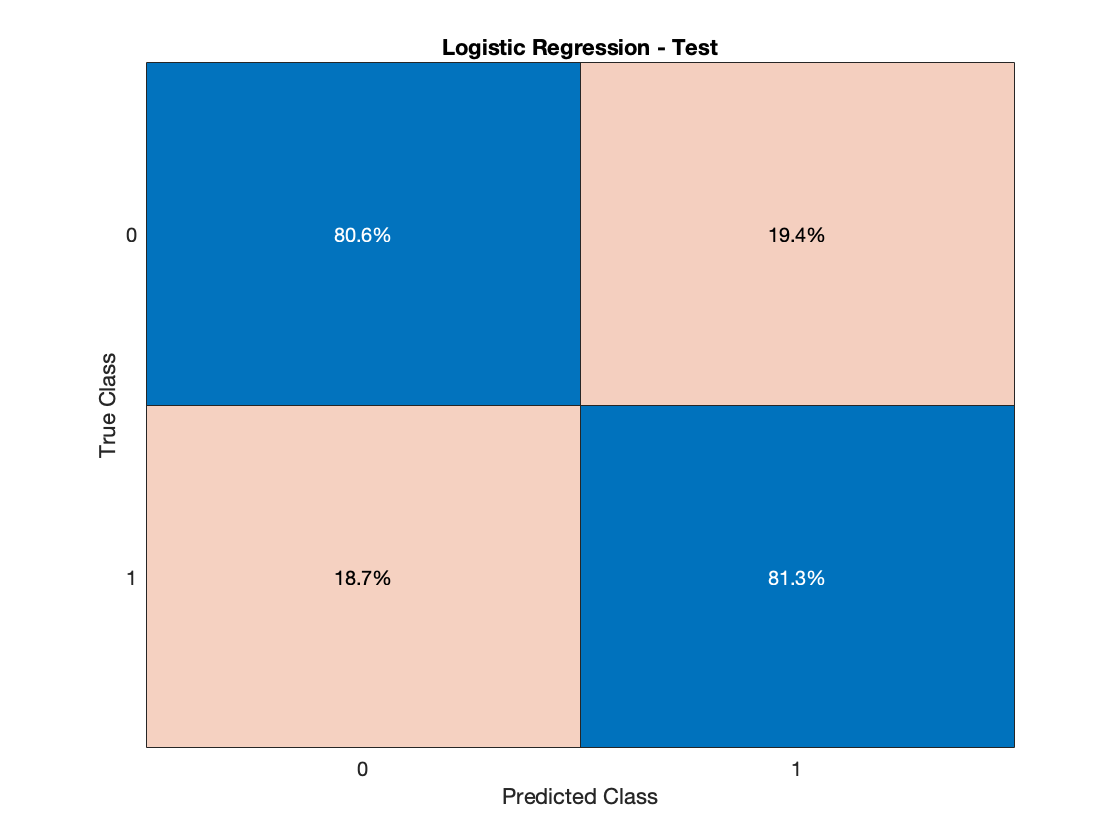

[LRpredYtest_,LRpredYtestScore] = predict(LRmdl,X_test);
LRpredYtest = double(LRpredYtest_>=0.4);
figure;
confusionchart(y_test,LRpredYtest, "Normalization","row-normalized", ...
    "Title",'Logistic Regression - Test');

                           Predicted Class 1      Predicted Class 2

True Class 1                  TN                            FP

True Class 2                  FN                            TP

LRconfMat = confusionmat(y_test,LRpredYtest)

LRconfMat =    834   201
    70   304


**i. Threshhold Metrics**

% Accuracy = (TP+TN)/(TP+TN+FP+FN)
LRacc = (LRconfMat(1,1)+LRconfMat(2,2))/sum(sum(LRconfMat)) 

LRacc = 0.8077

% Sensitivity/Recall = TP/(FN+TP)
LRsen = LRconfMat(2,2)/(LRconfMat(2,1)+LRconfMat(2,2)) 

LRsen = 0.8128

% Specificity(True Negative Rate) = TN/(TN+FP)
LRspe = LRconfMat(1,1)/(LRconfMat(1,1)+LRconfMat(1,2))

LRspe = 0.8058

% Precision = TP/(TN+TP)
LRpre = LRconfMat(2,2)/(LRconfMat(1,2)+LRconfMat(2,2))     

LRpre = 0.6020

% f1 score
LRf1  = 2/(1/LRpre + 1/LRsen)

LRf1 = 0.6917

% f2 score
LRf2 = (5*LRpre*LRsen)/(4*LRpre+LRsen) % false negatives are more important (predicting churned customer as non-churn is more costly)

LRf2 = 0.7596

% G-Mean
LRgmean = sqrt(LRsen * LRspe)

LRgmean = 0.8093

# B. Test the Random Forest Model

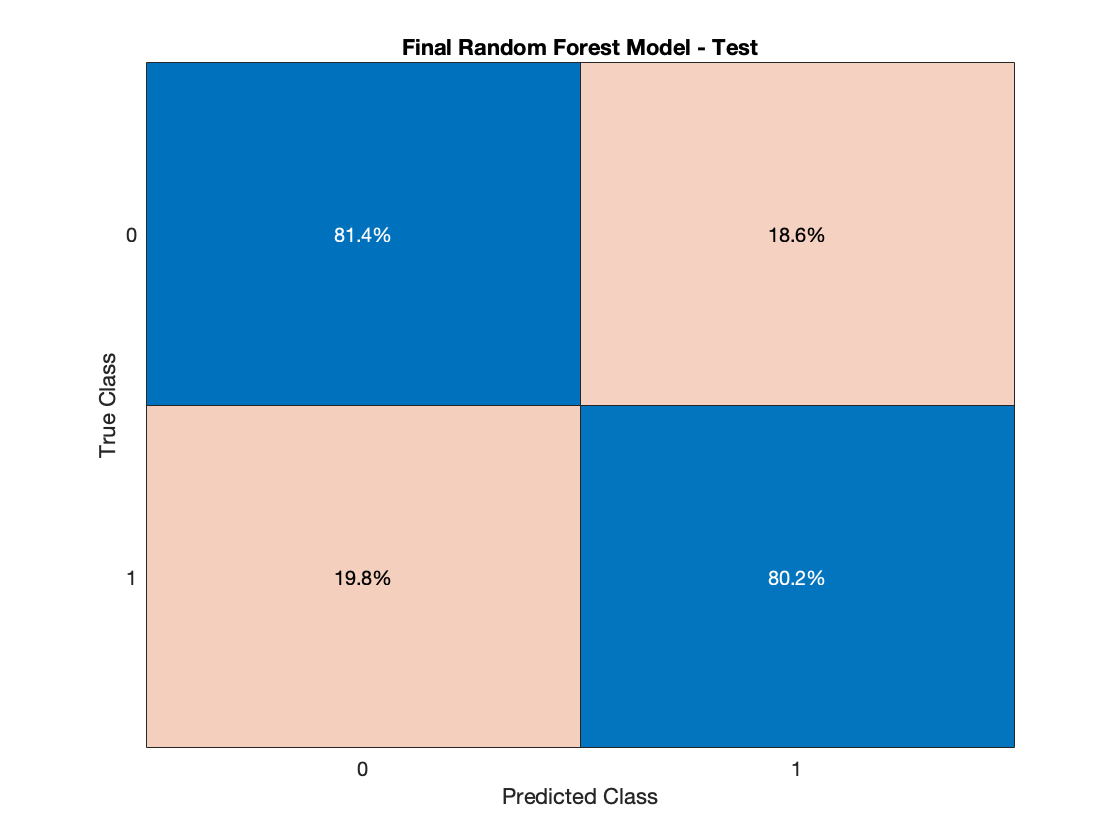

% confusion matrix for validation set
[RFpredYtestFinal,RFpredYtestScoreFinal] = predict(RFmdlFinal, X_test);
confusionchart(y_test,RFpredYtestFinal, ...
    'Normalization','row-normalized', ...
    'Title','Final Random Forest Model - Test');

% loss
RFlossFinal = loss(RFmdlFinal, X_test, y_test)

RFlossFinal = 0.1919

**i. Threshold Metrics**                   

                       Predicted Class 1      Predicted Class 2

True Class 1                  TN                            FP

True Class 2                  FN                            TP

RFconfMatFinal = confusionmat(y_test,RFpredYtestFinal)

RFconfMatFinal =    842   193
    74   300


% Accuracy = (TP+TN)/(TP+TN+FP+FN)
RFaccFinal = (RFconfMatFinal(1,1)+RFconfMatFinal(2,2))/sum(sum(RFconfMatFinal))

RFaccFinal = 0.8105

% Sensitivity/Recall = TP/(FN+TP)
RFsenFinal = RFconfMatFinal(2,2)/(RFconfMatFinal(2,1)+RFconfMatFinal(2,2))

RFsenFinal = 0.8021

% Specificity(True Negative Rate) = TN/(TN+FP)
RFspeFinal = RFconfMatFinal(1,1)/(RFconfMatFinal(1,1)+RFconfMatFinal(1,2))

RFspeFinal = 0.8135

% Precision = TP/(TN+TP)
RFpreFinal = RFconfMatFinal(2,2)/(RFconfMatFinal(1,2)+RFconfMatFinal(2,2))  

RFpreFinal = 0.6085

% f1 score
RFf1Final  = 2/(1/RFpreFinal + 1/RFsenFinal)

RFf1Final = 0.6920

% f2 score
RFf2Final = (5*RFpreFinal*RFsenFinal)/(4*RFpreFinal+RFsenFinal)

RFf2Final = 0.7541

% G-Mean
RFgmeanFinal = sqrt(RFsenFinal * RFspeFinal)

RFgmeanFinal = 0.8078

# C. Comparison of Models 

### C.1. ROC and AUC Curves

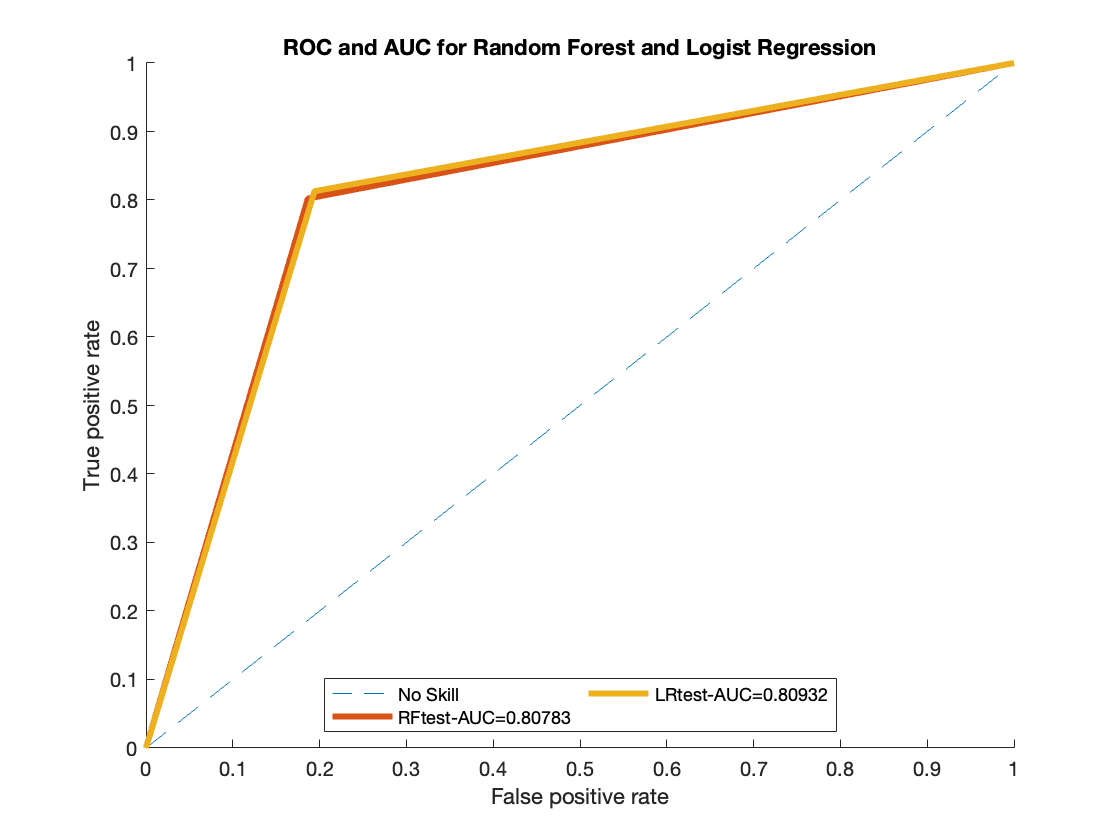

% Logistic regression AUC
[LRtestX,LRtestY,LRtestT,LRtestAUC] = perfcurve(y_test,LRpredYtest,1);
% Logistic regression Precision-Recall AUC
[LRtestXpr,LRtestYpr,LRtestTpr,LRtestAUCpr]=perfcurve(y_test,abs(LRpredYtestScore(:,2)),1,  'xCrit', 'reca', 'yCrit', 'prec');

% Random Forest AUC
[RFtestXfinal,RFtestYfinal,RFtestTfinal,RFtestAUCfinal] = perfcurve(y_test,RFpredYtestFinal,1);
% Random Forest Precision-Recall AUC
[RFtestXpr,RFtestYpr,RFtestTpr,RFtestAUCpr]=perfcurve(y_test,abs(RFpredYtestScoreFinal(:,2)),1,  'xCrit', 'reca', 'yCrit', 'prec');

figure;
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC and AUC for Random Forest and Logist Regression')

hold on;
plot([0, 1], [0, 1], "LineStyle","--", 'DisplayName',strcat('No Skill'))

plot(RFtestXfinal,RFtestYfinal,'LineWidth',3,'DisplayName',strcat('RFtest-AUC=',num2str(RFtestAUCfinal)))

plot(LRtestX,LRtestY,'LineWidth',3,'DisplayName',strcat('LRtest-AUC=',num2str(LRtestAUC)))

hold off
lgd = legend('Location','south');
lgd.NumColumns = 2;

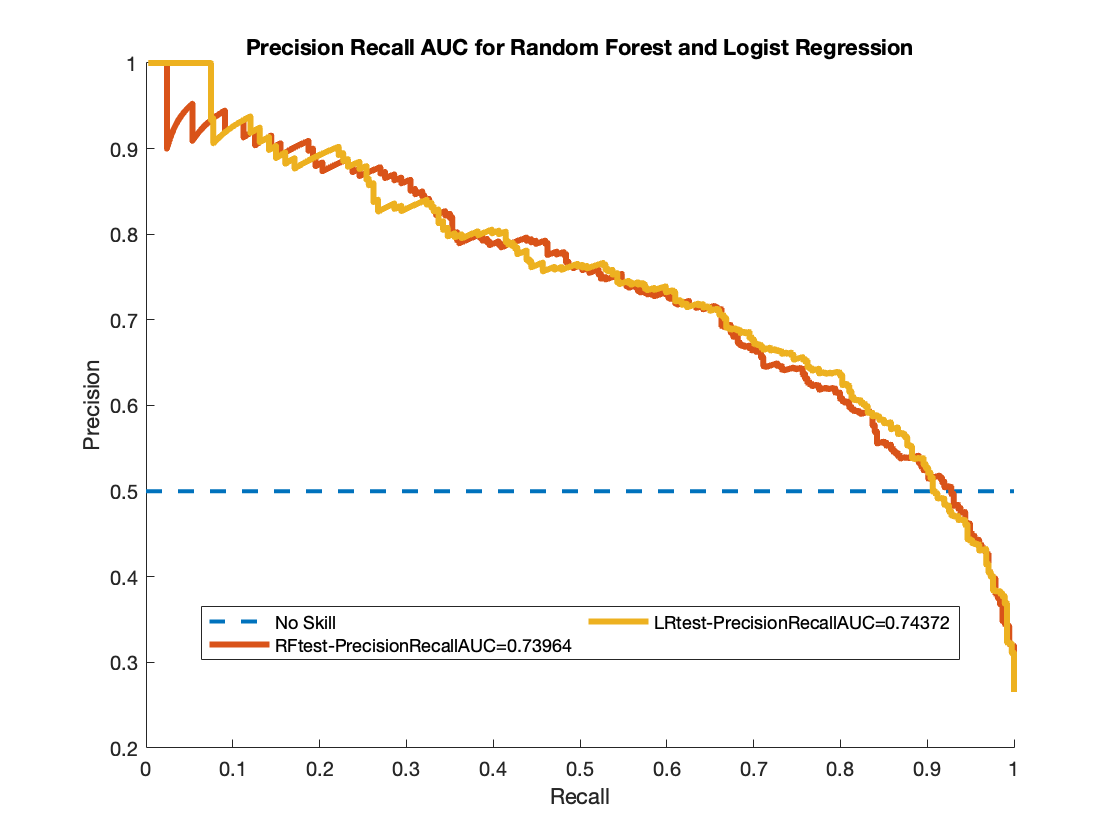

figure;
xlabel('Recall') 
ylabel('Precision')
title('Precision Recall AUC for Random Forest and Logist Regression')
hold on;
plot([0, 1], [0.5, 0.5], "LineStyle","--", 'Linewidth', 2, 'DisplayName',strcat('No Skill'))

plot(RFtestXpr,RFtestYpr,'LineWidth',3,'DisplayName',strcat('RFtest-PrecisionRecallAUC=',num2str(RFtestAUCpr)))

plot(LRtestXpr,LRtestYpr,'LineWidth',3,'DisplayName',strcat('LRtest-PrecisionRecallAUC=',num2str(LRtestAUCpr)))
hold off;
lgd = legend('Location','best');
lgd.NumColumns = 2;

### C.2. Performance measures

modelName = {'Logistic Regression', 'Random Forest'};
performanceMeasures = {'Accuracy', 'Sensitivity/Recall', 'Specificity/TNR',... 
    'Precision',  'f1-score', 'f2-score','G-Mean','AUC', 'Precision-Recall AUC'};
res = [LRacc,RFaccFinal;
       LRsen,RFsenFinal;
       LRspe,RFspeFinal;
       LRpre,RFpreFinal;
       LRf1, RFf1Final;
       LRf2,RFf1Final;
       LRgmean, RFgmeanFinal;
       LRtestAUC(1)*100, RFtestAUCfinal(1)*100;
       LRtestAUCpr(1)*100, RFtestAUCpr(1)*100];
restable= array2table(res,'RowNames',performanceMeasures,'VariableNames',modelName);
disp(restable);

                            Logistic Regression    Random Forest
                            ___________________    _____________
    Accuracy                      0.80767              0.8105   
    Sensitivity/Recall            0.81283             0.80214   
    Specificity/TNR                0.8058             0.81353   
    Precision                     0.60198             0.60852   
    f1-score                       0.6917             0.69204   
    f2-score                      0.75962             0.69204   
    G-Mean                        0.80931             0.80781   
    AUC                            80.932              80.783   
    Precision-Recall AUC           74.372              73.964   


The most important performance measures are Sensitivity/Recall (how many of the clients who actually leave were detected by the model) and precision (how many of the clients identified by the model actually left). Both models provide comparative results, Logistic Regression being slightly better with the much better  F2 Score and Recall. 

Logistic regression performs better when the number of noise variables is less than or equal to the number of explanatory variables and the random forest has a higher true and false positive rate as the number of explanatory variables increases in a dataset.

### C.3. Hypothesis testing

% accuracy of Logistic Regression
LR_matches = 0;
for i = 1:size(LRpredYtest,1)
    if LRpredYtest(i)==y_test(i)
        LR_matches = LR_matches + 1;
    end
end
LR_accuracy = LR_matches/size(LRpredYtest,1)

LR_accuracy = 0.8077

% accuracy of Random forest
RF_matches = 0;
for i = 1:size(RFpredYtestFinal,1)
    if RFpredYtestFinal(i)==y_test(i)
        RF_matches = RF_matches + 1;
    end
end
RF_accuracy = RF_matches/size(RFpredYtestFinal,1)

RF_accuracy = 0.8105

% compare accuracies of the two models
[h,p,LR_classloss,R_classloss] = testcholdout(LRpredYtest, RFpredYtestFinal,y_test)

h = logical
   0

p = 0.7185

LR_classloss = 0.1923

R_classloss = 0.1895

Comparing the two models, one can see that the accuracies and classification loss  of both models are very close to each other, however, Random Forest outperforming Logistic Regression only slightly. 

`h = 0` indicates to not reject the null hypothesis that the two models have equal predictive accuracies.

`h = 1` indicates to reject the null hypothesis that the two models have differing predictive accuracies.